## Initialize the FMCW Radar Computations

clear;
simulator = Simulator_revB();
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
% file_path = "B210_params.json";
% file_path = "B210_params_highBW.json";
% file_path = "B210_params_highvres.json";
 file_path = "B210_params_lowBW.json";
% file_path = "B210_params_sensing_system.json";
% file_path = "X310_params_100MHzBW.json";
% file_path = "realistic_params.json";
% file_path = "realistic_long_range.json";
simulator.load_params_from_JSON(david_path + file_path);


%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_usrp_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 1.50 GHz
	 Frequency Slope: 		 1.00 MHz/us
	 Idle Time: 			 18.44 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.56 us
	 ADC Samples: 			 64 
	 ADC Sample Rate: 		 3.20 MSps
	 Ramp End Time: 		 26.56 us
	 Chirp Tx Bandwidth: 		 26.56 MHz
	 Chirp Sampling Bandwidth: 	 20.00 MHz
	 ADC Sampling Period: 		 20.00 us
	 Chirp Cycle Time: 		 45.00 us
	 Chirp Wavelength: 		 199.86 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 11.52 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 479.67 m
	 Range Resolution 		 7.49 m
	 Max Velocity 			 1110.34 m/s
	 Velocity Resolution 		 8.67 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 28.80 MHz
	 Downsampling factor 		 9
	 Sweep time 			 26.56 us
	 Samples per chirp 		 1296.00 


### Initialize the target

simulator.load_target_realistic(100,-5);

### Initialize the Victim and Simulation Parameters

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

### Initialize the Attacker

%initialize the attacker
%initialize the attacker parameters
simulator.Attacker.initialize_attacker(...
                        simulator.Victim.FMCW_sampling_rate_Hz * 1e-6,...
                        simulator.Victim.StartFrequency_GHz,...
                        simulator.Victim.Chirp_Tx_Bandwidth_MHz);

%initialize the sensing subsystem's debugger
simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(0,simulator.Victim,1);
%set to change 1 to zero to disable

%specify the type of emulation ("target", 
        % "velocity spoof - noisy", 
        % "velocity spoof - similar velocity",
        % "range spoof - similar slope")

attack_type = "velocity spoof - similar velocity";
%attack_type = "velocity spoof - similar velocity,range spoof - similar slope ";
%initialize the attacker
simulator.Attacker.Subsystem_attacking.set_attack_mode(attack_type);

%if it is desired to specify a specific attack location
% simulator.Attacker.Subsystem_attacking.set_desired_attack_location(75,7);

## Save the victim chirp to a file

%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/chirp_full.bin";
simulator.save_to_file(simulator.Victim.chirp,path);

### Plot Tx Chirp to confirm correctness

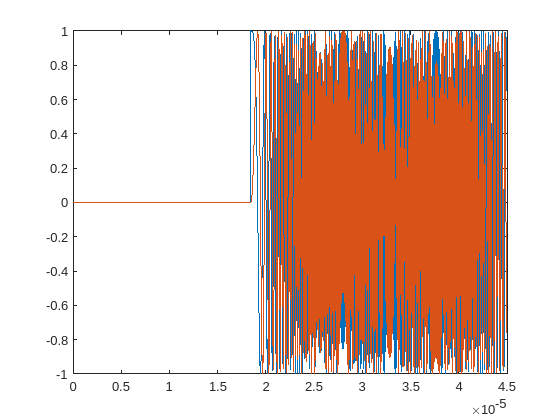

%plot the chirp signal
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
data = simulator.Victim.chirp;
plot(t,real(data),t,imag(data))

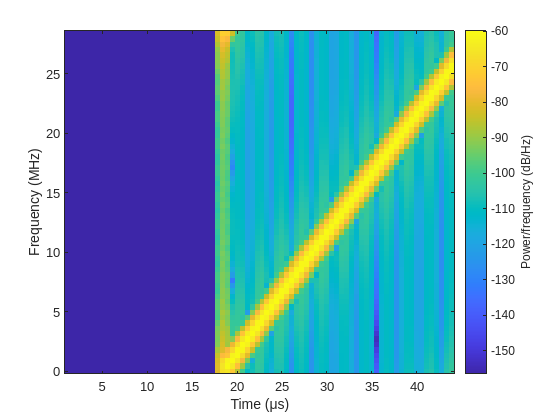

spectrogram(data,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

## Run Sensing Subsystem on USRP Device

### Read the data recorded by the offline simulation (and optionally plot to confirm correctness

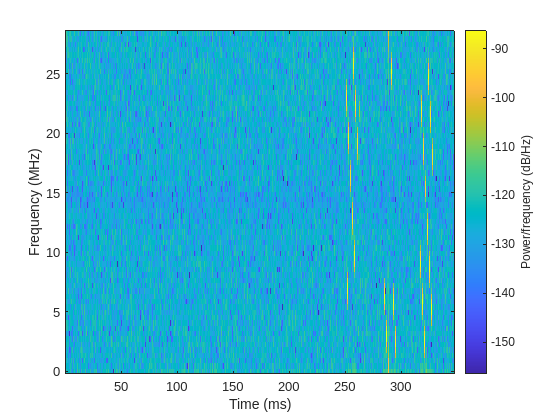

path = "/home/david/Documents/MATLAB_generated/sensing_stream.bin";
read_data = simulator.read_from_file(path,true);
samples_to_preview = 1e7;

%generate a spectrogram preview of the sampled signal if desired
clf;
spectrogram(read_data(1:samples_to_preview),64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

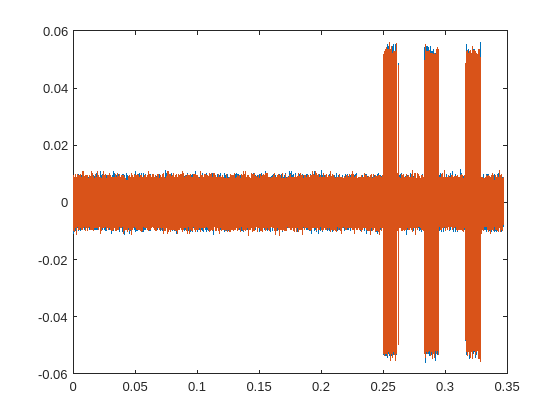

t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.FMCW_sampling_period_s * (samples_to_preview -1);
plot(t,real(read_data(1:samples_to_preview)),t,imag(read_data(1:samples_to_preview)))


%re-arrange for processing by the sensing subsystem
spb = 2040;
read_data = reshape(read_data,spb,[]).';

### Run a simulation of the sensing subsystem using USRP data instead of simulated data

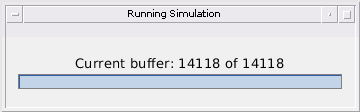

simulator.run_sensing_subsystem_with_USRP_data(read_data,true);

### Print out the estimated chirp characteristics:

% %print out the relevant information
fprintf("Number of Frames Detected: %d",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.num_captured_frames);

Number of Frames Detected: 23

fprintf("Average Frame Duration: %5.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_frame_duration);

Average Frame Duration: 33339.954 us

fprintf("Average Chirp Duration: %3.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_chirp_duration);

Average Chirp Duration: 45.000 us

fprintf("Average Slope: %1.3f MHz/us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_slope);

Average Slope: 0.999 MHz/us

### Save the most recently computed attack chirps to a file so that the attack configuration can use them

%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/attacking_chirps_full.bin";

%get the eumulated chirps
write_data = simulator.Attacker.Subsystem_attacking.emulated_chirps;

%reshape to be able to send to a file
write_data = reshape(write_data,[],1);
simulator.save_to_file(write_data,path);

## Use Computed Parameters to Run Attack Subsystem on MATLAB

### Read Rx data from MATLAB

path = "/home/david/Documents/MATLAB_generated/rx_data.bin";
read_data = simulator.read_from_file(path,true);

num_chirps = simulator.Victim.NumChirps;
samples_per_chirp = simulator.Victim.ChirpCycleTime_us * 1e-6 * simulator.Victim.FMCW_sampling_rate_Hz;
read_data = reshape(read_data,int32(samples_per_chirp),num_chirps,[]);

%determine the number of frames recorded
num_frames = size(read_data,3);

### Plot Rx Chirp to confirm correctness

Specify chirp:

chirp =1;

Specify frame:

frame = 21;
% the chirp signal
%chirp = 251;
%frame = 20;
first_frame = read_data(:,:,1);
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
clf;
subplot(1,2,1);
plot(t,real(read_data(:,chirp,frame)),t,imag(read_data(:,chirp,frame)))
subplot(1,2,2)
spectrogram(read_data(:,chirp,frame),64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

## Run the Simulation

%run the simulation (without an attacker for now)
frames_to_compute = 1;
simulator.run_simulation_with_attack(frames_to_compute,true);

## Verify C++ computations

### Spectrogram Generation

#### Get key initialization parameters

%print key properties for spectrum subsystem
num_rows = size(simulator.Attacker.Subsystem_spectrum_sensing.reshaped_signal,2);
samples_per_sampling_window = simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.num_samples_per_sampling_window;
fft_size = simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.fft_size;
samp_freq = simulator.Attacker.FMCW_sample_rate_Msps * 1e6;

fprintf(" rows: %d \n samples per sampling window: %d \n fft size: %d \n samp freq: %d",...
    num_rows,samples_per_sampling_window,fft_size,samp_freq);

#### Verify Hanning Window

%get the hanning window
path = "/home/david/Documents/MATLAB_generated/cpp_hanning_window.bin";
read_data = simulator.read_from_file(path,true);

%compare with the computed hanning window
compare = all(abs(read_data - simulator.Attacker.Subsystem_spectrum_sensing.spectogram_params.window) < 1e-5);
if compare
    fprintf("Hanning window matches")
else
    fprintf("Hanning window doesn't match")
end

#### Reshaped and windowed Received Signal - save received signal to file

%print the number of received samples
received_samples = size(simulator.Attacker.Subsystem_spectrum_sensing.received_signal,2);
fprintf(" receieved_samples: %d\n",received_samples)
%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/MATLAB_received_signal.bin";
simulator.save_to_file(simulator.Attacker.Subsystem_spectrum_sensing.received_signal.',path);

#### Reshape Received Signal - read and verify

%get the reshaped for fft signal
path = "/home/david/Documents/MATLAB_generated/cpp_reshaped_and_windowed_for_fft.bin";

read_data = simulator.read_from_file(path,true);
read_data_reshaped = reshape(read_data,fft_size,num_rows);

%compare with the computed hanning window

compare = all(abs(read_data_reshaped - simulator.Attacker.Subsystem_spectrum_sensing.windowed_signal) < 1e-5);

if compare
    fprintf("Reshaped and windowed signal for fft matches")
else
    fprintf("Reshaped and windowed signal for fft doesn't match")
end

#### Computed FFT - read and verify

path = "/home/david/Documents/MATLAB_generated/cpp_generated_spectrogram.bin";

read_data = simulator.read_from_file(path,false);
read_data_reshaped = reshape(read_data,fft_size,num_rows);
tolerance = 1e-1; %spectrogram converted to dB
compare = all(abs(read_data_reshaped - simulator.Attacker.Subsystem_spectrum_sensing.generated_spectogram) < tolerance);

if compare
    fprintf("Generated spectrogram matches")
else
    fprintf("Generated spectrogram doesn't match")
end

### Reshape the data to be processed by the sensing subsystem

%reshape the data into the correct format
read_data = reshape(read_data,spb,[]).';
%disp(read_data);
fclose(fileID);

## Offline Computation of Victim Radar Parameters

### Re-initialize the simulation

clear;
simulator = Simulator_revB();
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
 file_path = "B210_params.json";
% file_path = "B210_params_highBW.json";
% file_path = "B210_params_highvres.json";
% file_path = "B210_params_lowBW.json";
% file_path = "B210_params_sensing_system.json";
% file_path = "X310_params_100MHzBW.json";
% file_path = "realistic_params.json";
% file_path = "realistic_long_range.json";
simulator.load_params_from_JSON(david_path + file_path);


%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
%simulator.Victim.print_chirp_parameters;
%simulator.Victim.print_frame_parameters;
%simulator.Victim.print_performance_specs;
%simulator.Victim.print_FMCW_specs;

### Run the simulation

%process the data

for i = 1:size(read_data,1)
    
    %update positions
    [victim_pos, victim_vel,attacker_pos, attacker_vel, tgt_pos,tgt_vel] = ...
        simulator.FMCW_determine_positions_and_velocities(...
        simulator.Victim.current_frame,simulator.Victim.num_samples_sent);
    
    %attacker determines relative position and velocity of the victim
    simulator.Attacker.update_victim_pos_and_velocity(attacker_pos,victim_pos,attacker_vel, victim_vel);
    
    %receive the signal in the attacker
    received_sig = read_data(i,:);
    simulator.Attacker.receive_signal(received_sig);
end

% %print out the relevant information
fprintf("Average Frame Duration: %5.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_frame_duration);
fprintf("Average Chirp Duration: %3.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_chirp_duration);
fprintf("Average Slope: %1.3f MHz/us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_slope);